## Analiza cen chleba, paliwa oraz energii elektrycznej w 10 państwach w latach 2011-2021.

%importowanie danych
ger = readtable('Niemcy.csv', 'VariableNamingRule','preserve'  );
it = readtable('Włochy.xlsx', 'VariableNamingRule','preserve'  );
gb = readtable('Wielka_Brytania.csv', 'VariableNamingRule','preserve' );
usa = readtable('USA.xlsx', 'VariableNamingRule','preserve'  );
pl = readtable('Polska.xlsx', 'VariableNamingRule','preserve'  );
mex = readtable('Meksyk.xlsx', 'VariableNamingRule','preserve'  );
jap = readtable('Japonia.csv', 'VariableNamingRule','preserve'  );
esp = readtable('Hiszpania.csv', 'VariableNamingRule','preserve'  );
fr = readtable('Francja.csv', 'VariableNamingRule','preserve'  );
ch = readtable('Chiny.xlsx', 'VariableNamingRule','preserve'  );

## Wykresy cen wybranych dóbr w wybranych krajach na przestrzeni 2011-2021

Wszystkie ceny podane są w euro. Wykresy przedstawiają zmianę cen chleba, paliwa oraz 1 kWh energii na przestrzeni 2011-2021 oraz średnią cenę z omawianych państw.

Wykresy cen wybranych dóbr w wybranych krajach na przestrzeni 2011-2021

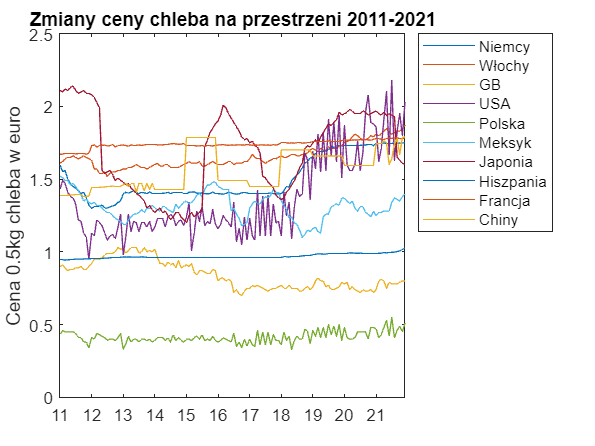

data = gb{:,1};
plot(data, ger{:,2}, data, it{:,2}, data, ...
    gb{:,2}, data, usa{:,2},data, pl{:,2},data, ...
    mex{:,2}, data, jap{:,2},data, esp{:,2},data, fr{:,2}, data, ch{:,2})
ylabel("Cena 0.5kg chleba w euro")
legend({'Niemcy','Włochy','GB','USA', 'Polska' ...
    ,'Meksyk','Japonia','Hiszpania','Francja', 'Chiny'},Location = 'bestoutside');
title("Zmiany ceny chleba na przestrzeni 2011-2021")

## Średnia cena chleba 2011-2021.

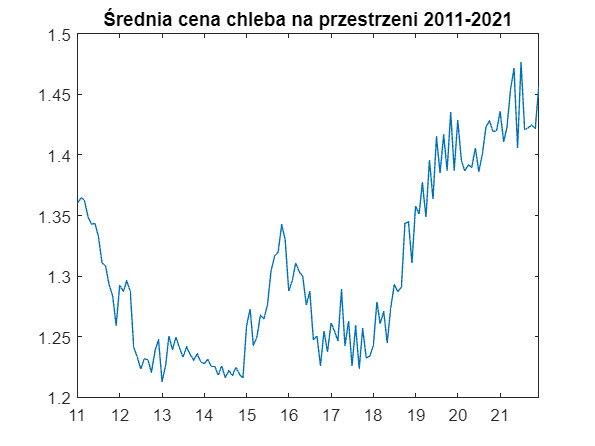

srednia = (ger{:,2} + it{:,2} + gb{:,2} + usa{:,2} + pl{:,2} + mex{:,2}+jap{:,2}+esp{:,2}+fr{:,2}+ch{:,2})./10;
plot(data,srednia)
title("Średnia cena chleba na przestrzeni 2011-2021")

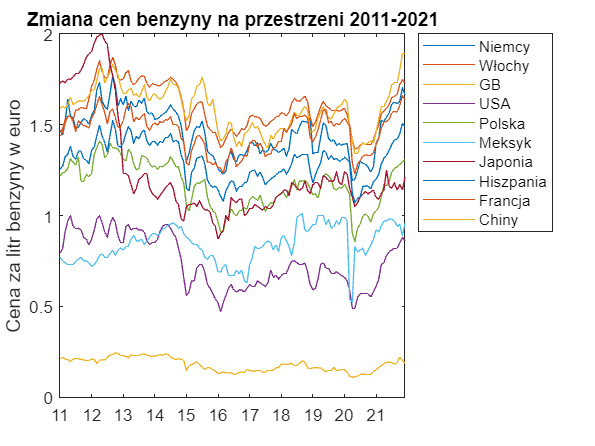

plot(data, ger{:,3}, data, it{:,3}, data, ...
    gb{:,3}, data, usa{:,3},data, pl{:,3},data, ...
    mex{:,3}, data, jap{:,3},data, esp{:,3},data, fr{:,3}, data, ch{:,3})
title("Zmiana cen benzyny na przestrzeni 2011-2021")
legend({'Niemcy','Włochy','GB','USA', 'Polska' ...
    ,'Meksyk','Japonia','Hiszpania','Francja', 'Chiny'},'Location','bestoutside')
ylabel('Cena za litr benzyny w euro')

## Średnia cena paliwa 2011-2021.

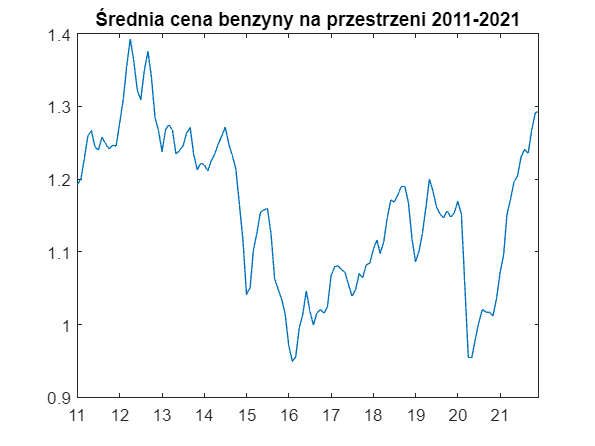

srednia_benzyna = (ger{:,3} + it{:,3} + gb{:,3} + usa{:,3} + pl{:,3} + mex{:,3}+jap{:,3}+esp{:,3}+fr{:,3}+ch{:,3})./10;
plot(data,srednia_benzyna)
title("Średnia cena benzyny na przestrzeni 2011-2021")

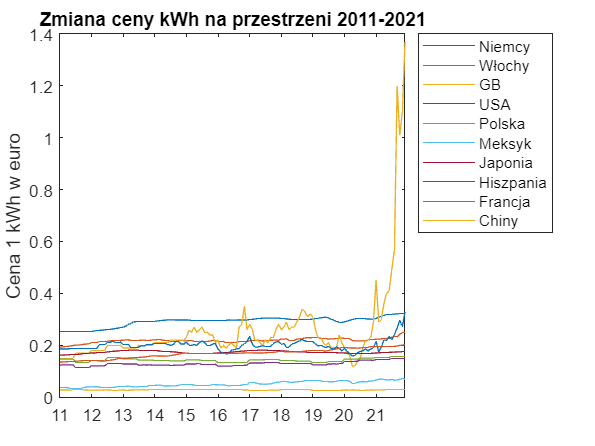

plot(data, ger{:,4}, data, it{:,4}, data, ...
    gb{:,4}, data, usa{:,4},data, pl{:,4},data, ...
    mex{:,4}, data, jap{:,4},data, esp{:,4},data, fr{:,4}, data, ch{:,4})
title("Zmiana ceny kWh na przestrzeni 2011-2021")
legend({'Niemcy','Włochy','GB','USA', 'Polska' ...
    ,'Meksyk','Japonia','Hiszpania','Francja','Chiny'},'Location','bestoutside')
ylabel("Cena 1 kWh w euro")

## Średnia cena 1kWh 2011-2021.

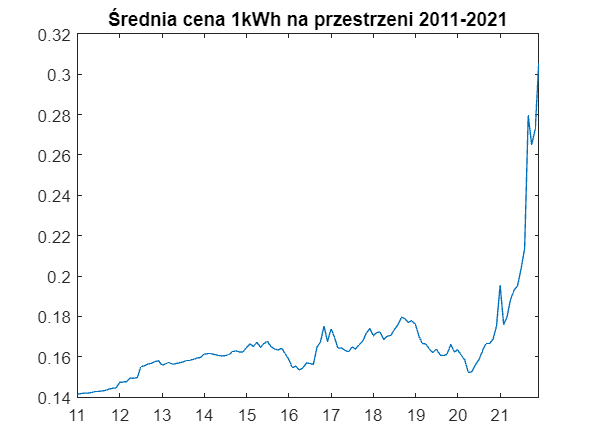

srednia_kWh = (ger{:,4} + it{:,4} + gb{:,4} + usa{:,4} + pl{:,4} + mex{:,4}+jap{:,4}+esp{:,4}+fr{:,4}+ch{:,4})./10;
plot(data,srednia_kWh)
title("Średnia cena 1kWh na przestrzeni 2011-2021")

## Zmiana średniej krajowej na przestrzeni 2011-2021

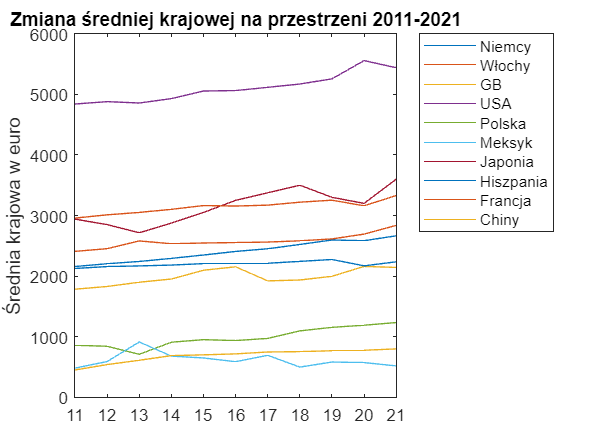

plot(data(1:12:132), ger{:,5}(1:12:132), data(1:12:132), it{:,5}(1:12:132), data(1:12:132), ...
    gb{:,5}(1:12:132), data(1:12:132), usa{:,5}(1:12:132),data(1:12:132), pl{:,5}(1:12:132),data(1:12:132), ...
    mex{:,5}(1:12:132), data(1:12:132), jap{:,5}(1:12:132),data(1:12:132), esp{:,5}(1:12:132),data(1:12:132), fr{:,5}(1:12:132), data(1:12:132), ch{:,5}(1:12:132))
title("Zmiana średniej krajowej na przestrzeni 2011-2021")
legend({'Niemcy','Włochy','GB','USA', 'Polska' ...
    ,'Meksyk','Japonia','Hiszpania','Francja','Chiny'},'Location','bestoutside')
ylabel("Średnia krajowa w euro")

## Średnia krajowa 2011-2021.

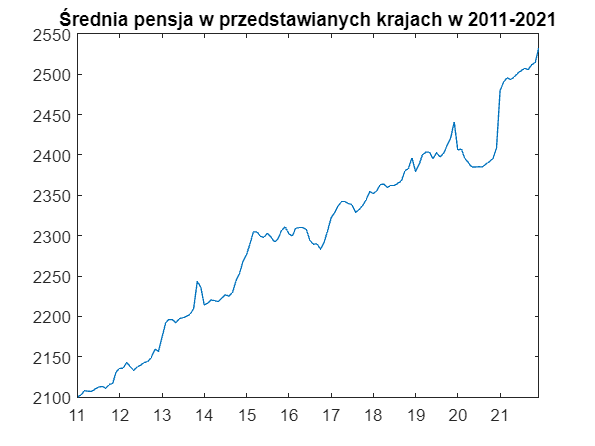

srednia_krajowa = (ger{:,5} + it{:,5} + gb{:,5} + usa{:,5} + pl{:,5} + mex{:,5}+jap{:,5}+esp{:,5}+fr{:,5}+ch{:,5})./10;
plot(data,srednia_krajowa)
title("Średnia pensja w przedstawianych krajach w 2011-2021")

## Ile dóbr można kupić w poszczególnych krajach na przestrzeni 2011-2022?

Wykresy przedstawiają ile jednostek danego towaru można kupić w poszczególnych krajach za średnią pensję. (0,5kg chleba, 1 litr paliwa, 1kWh energii)

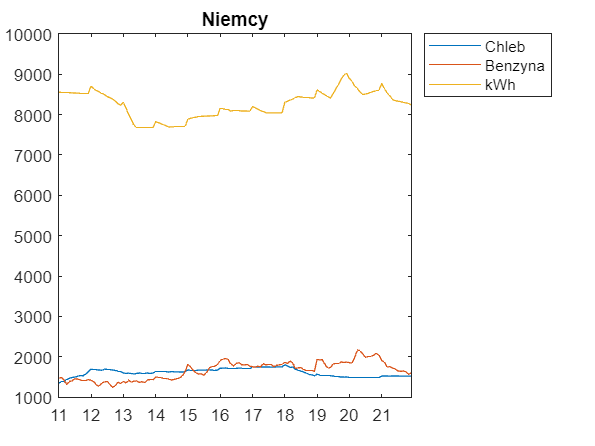

plot(data, ger{:,5}./ger{:,2}, data, ger{:,5}./ger{:,3}, data,ger{:,5}./ger{:,4})
title("Niemcy")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

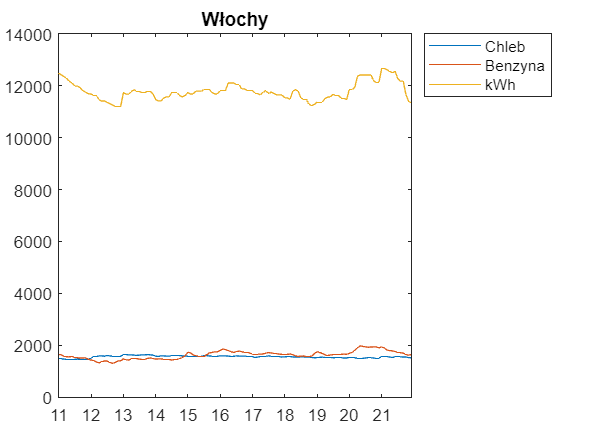

plot(data, it{:,5}./it{:,2}, data, it{:,5}./it{:,3}, data,it{:,5}./it{:,4})
title("Włochy")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

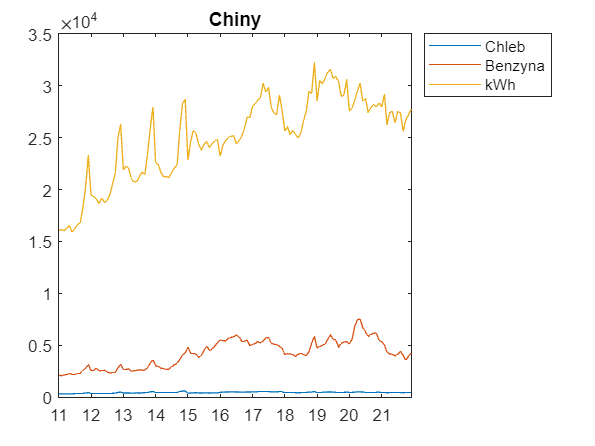

plot(data, ch{:,5}./ch{:,2}, data, ch{:,5}./ch{:,3}, data,ch{:,5}./ch{:,4})
title("Chiny")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

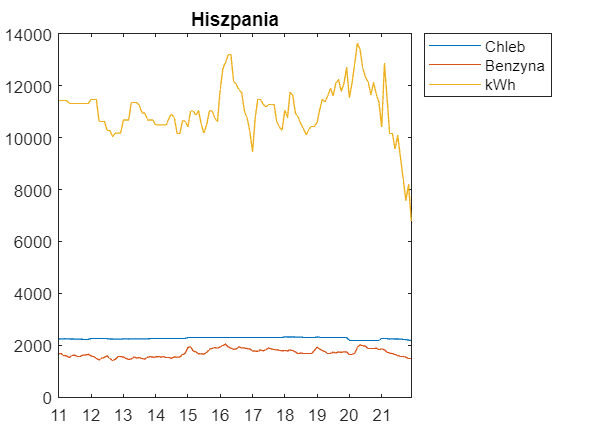

plot(data, esp{:,5}./esp{:,2}, data, esp{:,5}./esp{:,3}, data,esp{:,5}./esp{:,4})
title("Hiszpania")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

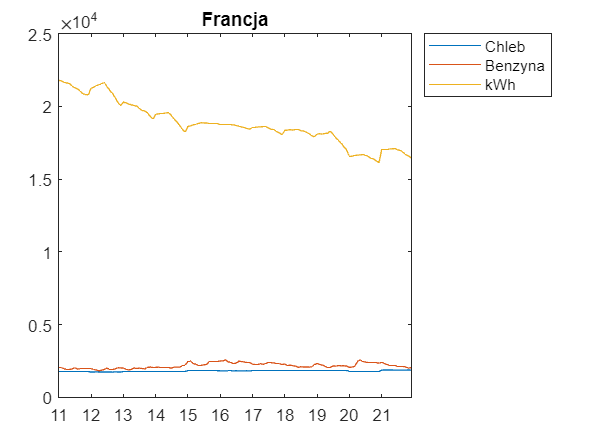

plot(data, fr{:,5}./fr{:,2}, data, fr{:,5}./fr{:,3}, data,fr{:,5}./fr{:,4})
title("Francja")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

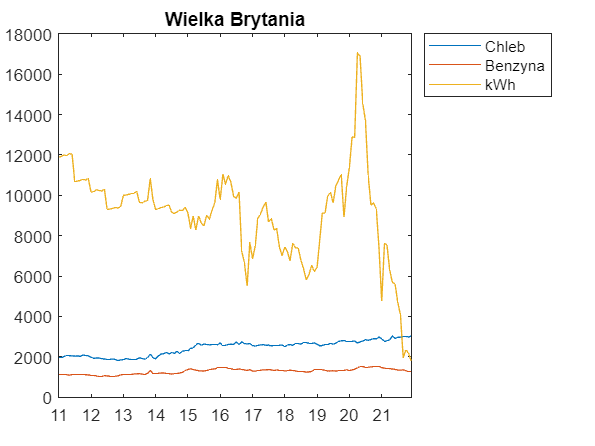

plot(data, gb{:,5}./gb{:,2}, data, gb{:,5}./gb{:,3}, data,gb{:,5}./gb{:,4})
title("Wielka Brytania")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

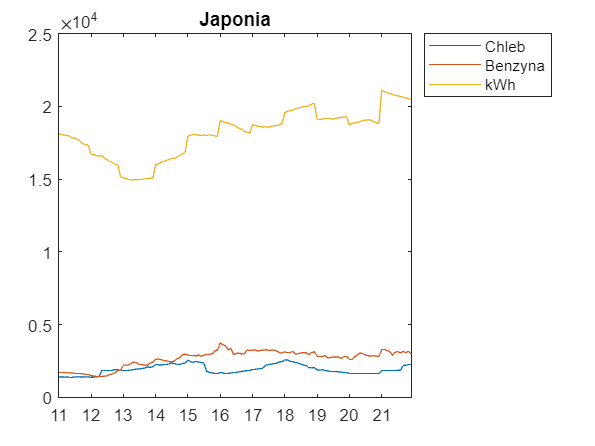

plot(data, jap{:,5}./jap{:,2}, data, jap{:,5}./jap{:,3}, data,jap{:,5}./jap{:,4})
title("Japonia")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

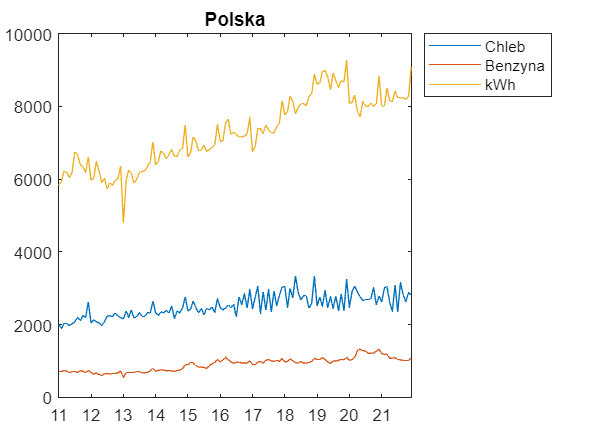

plot(data, pl{:,5}./pl{:,2}, data, pl{:,5}./pl{:,3}, data,pl{:,5}./pl{:,4})
title("Polska")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

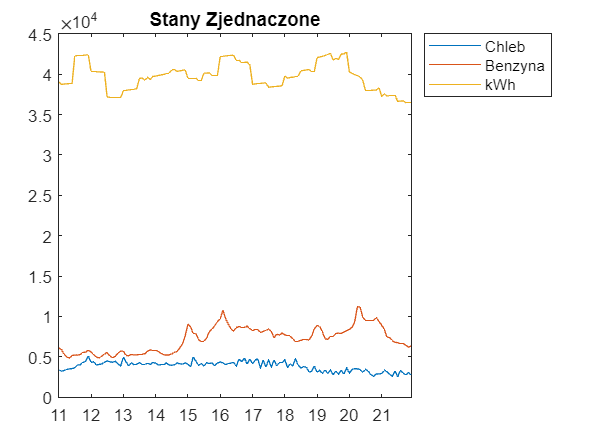

plot(data, usa{:,5}./usa{:,2}, data, usa{:,5}./usa{:,3}, data,usa{:,5}./usa{:,4})
title("Stany Zjednaczone")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

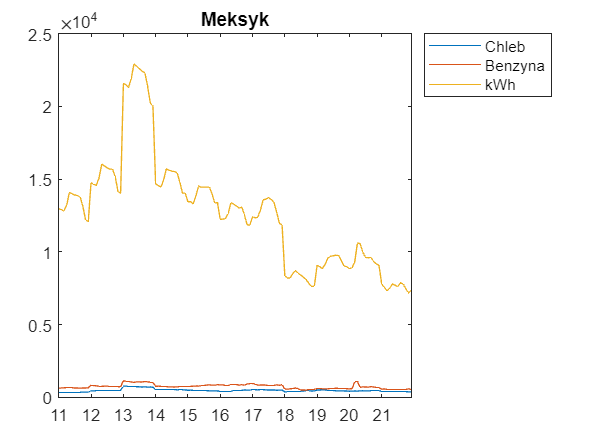

plot(data, mex{:,5}./mex{:,2}, data, mex{:,5}./mex{:,3}, data,mex{:,5}./mex{:,4})
title("Meksyk")
legend({'Chleb', 'Benzyna', 'kWh'},'Location','bestoutside')

## Porównanie ile dóbr można kupić w poszczególnych krajach za średnią krajową:

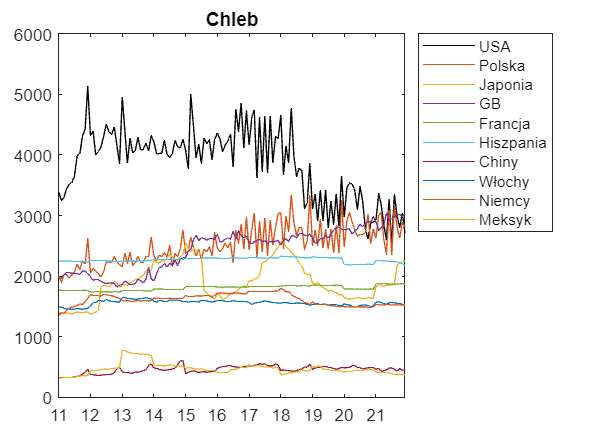

plot(data, usa{:,5}./usa{:,2},'black', data, pl{:,5}./pl{:,2}, data,jap{:,5}./jap{:,2}, data, gb{:,5}./gb{:,2}, data, fr{:,5}./fr{:,2}, data,  esp{:,5}./esp{:,2}, data, ch{:,5}./ch{:,2}, data, it{:,5}./it{:,2}, data, ger{:,5}./ger{:,2},data, mex{:,5}./mex{:,2}  )
legend({'USA', 'Polska','Japonia','GB', 'Francja', 'Hiszpania', 'Chiny', 'Włochy', 'Niemcy', 'Meksyk'},'Location','bestoutside')
title("Chleb")

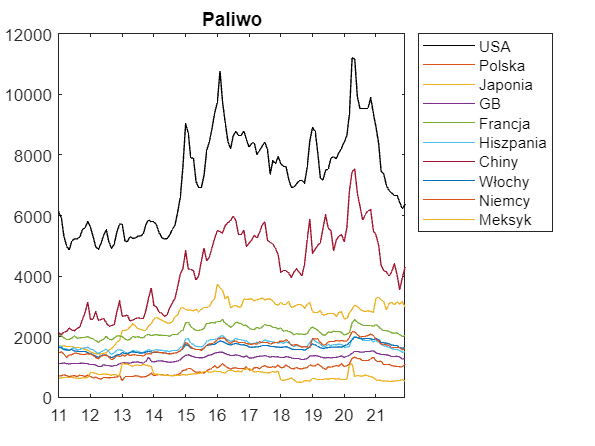

plot(data, usa{:,5}./usa{:,3}, 'black', data, pl{:,5}./pl{:,3}, data,jap{:,5}./jap{:,3}, data, gb{:,5}./gb{:,3}, data, fr{:,5}./fr{:,3}, data,  esp{:,5}./esp{:,3}, data, ch{:,5}./ch{:,3}, data, it{:,5}./it{:,3}, data, ger{:,5}./ger{:,3},data, mex{:,5}./mex{:,3}  )
legend({'USA', 'Polska','Japonia','GB', 'Francja', 'Hiszpania', 'Chiny', 'Włochy', 'Niemcy', 'Meksyk'},'Location','bestoutside')
title("Paliwo")

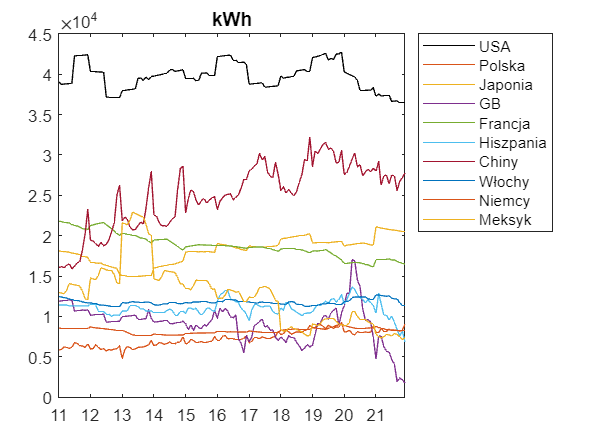

plot(data, usa{:,5}./usa{:,4}, 'black', data, pl{:,5}./pl{:,4}, data,jap{:,5}./jap{:,4}, data, gb{:,5}./gb{:,4}, data, fr{:,5}./fr{:,4}, data,  esp{:,5}./esp{:,4}, data, ch{:,5}./ch{:,4}, data, it{:,5}./it{:,4}, data, ger{:,5}./ger{:,4},data, mex{:,5}./mex{:,4}  )
legend({'USA', 'Polska','Japonia','GB', 'Francja', 'Hiszpania', 'Chiny', 'Włochy', 'Niemcy', 'Meksyk'},'Location','bestoutside')
title("kWh")

## Analiza danych przedstawiona w tabeli:

panstwo = ["Niemcy"; "Włochy"; "Wielka Brytania" ;... 
    "USA"; "Polska";"Meksyk"; "Japonia"; ...
    "Hiszpania"; "Francja"; "Chiny"];
najnizsza_cena_chleba = [min(ger{:,2});min(it{:,2});min(gb{:,2}); ...
    min(usa{:,2});min(pl{:,2});min(mex{:,2});min(jap{:,2}); ...
    min(esp{:,2});min(fr{:,2});min(ch{:,2})];
najwyzsza_cena_chleba = [max(ger{:,2});max(it{:,2});max(gb{:,2}); ...
    max(usa{:,2});max(pl{:,2});max(mex{:,2});max(jap{:,2}); ...
    max(esp{:,2});max(fr{:,2});max(ch{:,2})];
najnizsza_cena_paliwa = [min(ger{:,3});min(it{:,3});min(gb{:,3}); ...
    min(usa{:,3});min(pl{:,3});min(mex{:,3});min(jap{:,3}); ...
    min(esp{:,3});min(fr{:,3});min(ch{:,3})];
najwyzsza_cena_paliwa = [max(ger{:,3});max(it{:,3});max(gb{:,3}); ...
    max(usa{:,3});max(pl{:,3});max(mex{:,3});max(jap{:,3}); ...
    max(esp{:,3});max(fr{:,3});max(ch{:,3})];
najnizsza_cena_kwh = [min(ger{:,4});min(it{:,4});min(gb{:,4}); ...
    min(usa{:,4});min(pl{:,4});min(mex{:,4});min(jap{:,4}); ...
    min(esp{:,4});min(fr{:,4});min(ch{:,4})];
najwyzsza_cena_kwh = [max(ger{:,4});max(it{:,4});max(gb{:,4}); ...
    max(usa{:,4});max(pl{:,4});max(mex{:,4});max(jap{:,4}); ...
    max(esp{:,4});max(fr{:,4});max(ch{:,4})];
najnizsza_srednia_krajowa = [min(ger{:,5});min(it{:,5});min(gb{:,5}); ...
    min(usa{:,5});min(pl{:,5});min(mex{:,5});min(jap{:,5}); ...
    min(esp{:,5});min(fr{:,5});min(ch{:,5})];
najwyzsza_srednia_krajowa = [max(ger{:,5});max(it{:,5});max(gb{:,5}); ...
    max(usa{:,5});max(pl{:,5});max(mex{:,5});max(jap{:,5}); ...
    max(esp{:,5});max(fr{:,5});max(ch{:,5})];
zmiana_chleb = transpose(1:10);
zmiana_paliwo = transpose(1:10);
zmiana_kwh = transpose(1:10);
zmiana_placa = transpose(1:10);

for n = 1:10 
    zmiana_chleb(n) = ((analiza{n,3} - analiza{n,2})/analiza{n,2})*100;
end
zmiana_chleb = (round(zmiana_chleb));

for n = 1:10 
    zmiana_paliwo(n) = ((analiza{n,6} - analiza{n,5})/analiza{n,5})*100;
end
zmiana_paliwo = (round(zmiana_paliwo));

for n = 1:10 
    zmiana_kwh(n) = ((analiza{n,9} - analiza{n,8})/analiza{n,8})*100;
end
zmiana_kwh = (round(zmiana_kwh));

for n = 1:10 
    zmiana_placa(n) = ((analiza{n,12} - analiza{n,11})/analiza{n,11})*100;
end
zmiana_placa = (round(zmiana_placa));

## W tabeli podane są minimalne oraz maksymalne ceny w podanym przedziale czasowym oraz ich procentowy wzrost.

analiza = table(panstwo,najnizsza_cena_chleba,najwyzsza_cena_chleba,...
    zmiana_chleb,najnizsza_cena_paliwa,najwyzsza_cena_paliwa, zmiana_paliwo ... 
    ,najnizsza_cena_kwh,najwyzsza_cena_kwh, zmiana_kwh,najnizsza_srednia_krajowa, najwyzsza_srednia_krajowa, zmiana_placa);

analiza.Properties.VariableNames = ["Państwo","Najniższa cena chleba","Najwyższa cena chleba", "Zmiana ceny chleba w procentach", "Najniższa cena paliwa", "Najwyższa cena paliwa", "Zmiana ceny paliwa w procentach", "Najniższa cena kWh", "Najwyższa cena kWh", "Zmiana ceny kWh w procentach", "Najniższa średnia krajowa", "Najwyższa średnia krajowa", "Zmiana średniej krajowej w procentach"]

analiza = 10×13 table
         Państwo         Najniższa cena chleba    Najwyższa cena chleba    Zmiana ceny chleba w procentach    Najniższa cena paliwa    Najwyższa cena paliwa    Zmiana ceny paliwa w procentach    Najniższa cena kWh    Najwyższa cena kWh    Zmiana ceny kWh w procentach    Najniższa średnia krajowa    Najwyższa średnia krajowa    Zmiana średniej krajowej w procentach
    _________________    _____________________    _____________________    _______________________________    _____________________    _____________________    _______________________________    __________________    __________________  

panstwa = {ger, it, gb, usa, pl, mex, jap, esp, fr, ch};
ile_chleb = transpose(1:10);
ile_paliwo = transpose(1:10);
ile_kwh = transpose(1:10);

for n = 1:10
    ile_chleb(n) = round(sum(panstwa{:,n}{:,5}./panstwa{:,n}{:,2})/132);
end

for n = 1:10
    ile_paliwo(n) = round(sum(panstwa{:,n}{:,5}./panstwa{:,n}{:,3})/132);
end

for n = 1:10
    ile_kwh(n) = round(sum(panstwa{:,n}{:,5}./panstwa{:,n}{:,4})/132);
end

## Średnia ilość towaru jaką można kupić za średnią krajową 2011-2021

analiza2 = table(panstwo, ile_chleb, ile_paliwo, ile_kwh);
analiza2.Properties.VariableNames = ["Państwo", "Chleb", "Paliwo", "kWh"]

analiza2 = 10×4 table
         Państwo         Chleb    Paliwo     kWh 
    _________________    _____    ______    _____

    "Niemcy"             1611      1663      8251
    "Włochy"             1558      1628     11786
    "Wielka Brytania"    2443      1282      9091
    "USA"                3846      7191     39697
    "Polska"             2518       906      7276
    "Meksyk"              471       742     12650
    "Japonia"            1913      2665     18141
    "Hiszpania"          2268      1704     11036
    "Francja"            1806      2170     18804
    "Chiny"               457      4220     24970
